syms theta_B theta_K g
syms L_1 L_2 G_1 G_2 m_1 m_2 I_1 I_2
syms psi_1 psi_dot_1 psi_ddot_1 psi_2 psi_dot_2 psi_ddot_2
syms tau_1 tau_2

eqn1 = (m_1*G_1^2 + m_2*G_2^2 + 2*m_2*cos(psi_1 - psi_2)*G_2*L_1 + m_2*L_1^2 + I_1)*psi_ddot_1 + (-G_2*L_1*m_2*sin(psi_1 - psi_2))*psi_dot_1^2 + (2*G_2*L_1*m_2*psi_dot_2*sin(psi_1 - psi_2))*psi_dot_1 + m_2*psi_ddot_2*G_2^2 + L_1*m_2*sin(psi_1 - psi_2)*G_2*psi_dot_2^2 + L_1*m_2*psi_ddot_2*cos(psi_1 - psi_2)*G_2 + G_1*g*m_1*cos(psi_1) + L_1*g*m_2*cos(psi_1) == tau_1

$$eqn1 = {\ddot{\psi }}_{1}\,\left(m_{1}\,{G_{1}}^{2}+m_{2}\,{G_{2}}^{2}+2\,m_{2}\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,L_{1}+m_{2}\,{L_{1}}^{2}+I_{1}\right)+{G_{2}}^{2}\,m_{2}\,{\ddot{\psi }}_{2}+G_{1}\,g\,m_{1}\,\cos\left(\psi_{1}\right)+L_{1}\,g\,m_{2}\,\cos\left(\psi_{1}\right)-G_{2}\,L_{1}\,m_{2}\,{{\dot{\psi }}_{1}}^{2}\,\sin\left(\psi_{1}-\psi_{2}\right)+G_{2}\,L_{1}\,m_{2}\,{{\dot{\psi }}_{2}}^{2}\,\sin\left(\psi_{1}-\psi_{2}\right)+G_{2}\,L_{1}\,m_{2}\,{\ddot{\psi }}_{2}\,\cos\left(\psi_{1}-\psi_{2}\right)+2\,G_{2}\,L_{1}\,m_{2}\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}\,\sin\left(\psi_{1}-\psi_{2}\right)=\tau_{1}$$

eqn2 = (m_2*G_2^2 + I_2)*psi_ddot_2 + G_2^2*m_2*psi_ddot_1 + G_2*g*m_2*cos(psi_2) - 2*G_2*L_1*m_2*psi_dot_1^2*sin(psi_1 - psi_2) + G_2*L_1*m_2*psi_ddot_1*cos(psi_1 - psi_2) == tau_2

$$eqn2 = {\ddot{\psi }}_{2}\,\left(m_{2}\,{G_{2}}^{2}+I_{2}\right)+{G_{2}}^{2}\,m_{2}\,{\ddot{\psi }}_{1}+G_{2}\,g\,m_{2}\,\cos\left(\psi_{2}\right)-2\,G_{2}\,L_{1}\,m_{2}\,{{\dot{\psi }}_{1}}^{2}\,\sin\left(\psi_{1}-\psi_{2}\right)+G_{2}\,L_{1}\,m_{2}\,{\ddot{\psi }}_{1}\,\cos\left(\psi_{1}-\psi_{2}\right)=\tau_{2}$$


s = solve([eqn1 eqn2],[psi_ddot_1 psi_ddot_2])

s = struct with fields:
    psi_ddot_1: -(G_2^2*m_2*tau_2 - G_2^2*m_2*tau_1 - I_2*tau_1 - G_2^3*g*m_2^2*cos(psi_2) + G_2^3*L_1*m_2^2*psi_dot_1^2*sin(psi_1 - psi_2) + G_2^3*L_1*m_2^2*psi_dot_2^2*sin(psi_1 - psi_2) + G_2^2*L_1*g*m_2^2*cos(psi_1) + G_1*I_2*g*m_1*cos(psi_1) + I…
    psi_ddot_2: (I_1*tau_2 + G_1^2*m_1*tau_2 - G_2^2*m_2*tau_1 + G_2^2*m_2*tau_2 + L_1^2*m_2*tau_2 - G_2^3*g*m_2^2*cos(psi_2) + 2*G_2*L_1^3*m_2^2*psi_dot_1^2*sin(psi_1 - psi_2) + G_2^3*L_1*m_2^2*psi_dot_1^2*sin(psi_1 - psi_2) + G_2^3*L_1*m_2^2*psi_do…


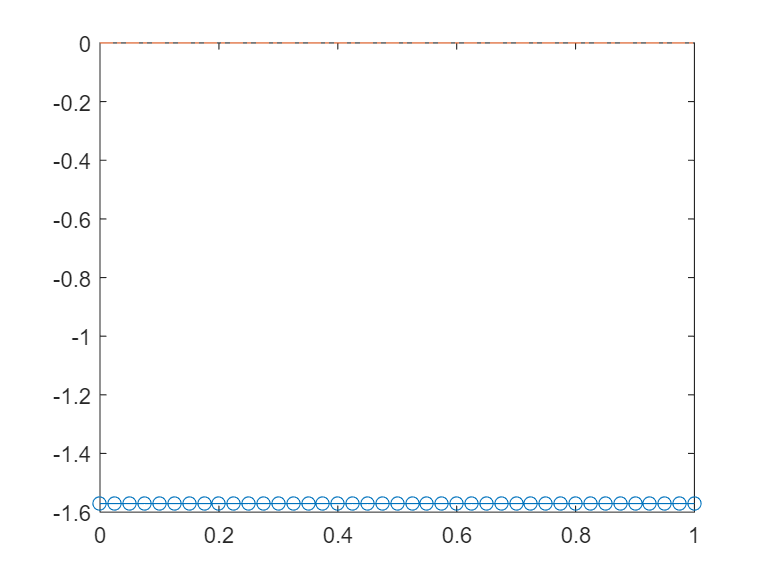

tau_1 = 0;
tau_2 = 0;
tspan = [0 1];
y0 = [-pi/2 0 -pi/2 0];
[t,y] = ode45(@(t,y) two_link_ode(t,y,tau_1,tau_2), tspan, y0);
plot(t,y(:,1),'-o',t,y(:,2),'-.')

function dy = two_link_ode(t,y,tau_1,tau_2)
L_1 = 0.15; L_2 = 0.1; G_1 = 0.08; G_2 = 0.06; g = 9.81;
m_1 = 0.1; m_2 = 0.1; I_1 = 0.01; I_2 = 0.01;
syms psi_1 psi_dot_1 psi_2 psi_dot_2
sub_vars = [psi_1; psi_dot_1; psi_2; psi_dot_2;];
dy_old = [psi_dot_1; -(G_2^2*m_2*tau_2 - G_2^2*m_2*tau_1 - I_2*tau_1 - G_2^3*g*m_2^2*cos(psi_2) + G_2^3*L_1*m_2^2*psi_dot_1^2*sin(psi_1 - psi_2) + G_2^3*L_1*m_2^2*psi_dot_2^2*sin(psi_1 - psi_2) + G_2*L_1*m_2*cos(psi_1 - psi_2)*tau_2 + G_2^2*L_1*g*m_2^2*cos(psi_1) + G_1*I_2*g*m_1*cos(psi_1) + I_2*L_1*g*m_2*cos(psi_1) + 2*G_2^3*L_1*m_2^2*psi_dot_1*psi_dot_2*sin(psi_1 - psi_2) - G_2^2*L_1*g*m_2^2*cos(psi_1 - psi_2)*cos(psi_2) + G_1*G_2^2*g*m_1*m_2*cos(psi_1) + 2*G_2^2*L_1^2*m_2^2*psi_dot_1^2*cos(psi_1 - psi_2)*sin(psi_1 - psi_2) - G_2*I_2*L_1*m_2*psi_dot_1^2*sin(psi_1 - psi_2) + G_2*I_2*L_1*m_2*psi_dot_2^2*sin(psi_1 - psi_2) + 2*G_2*I_2*L_1*m_2*psi_dot_1*psi_dot_2*sin(psi_1 - psi_2))/(I_1*I_2 + G_2^2*L_1^2*m_2^2 + G_1^2*I_2*m_1 + G_2^2*I_1*m_2 + G_2^2*I_2*m_2 + I_2*L_1^2*m_2 + G_1^2*G_2^2*m_1*m_2 - G_2^2*L_1^2*m_2^2*cos(psi_1 - psi_2)^2 + 2*G_2*I_2*L_1*m_2*cos(psi_1 - psi_2)); psi_dot_2; (I_1*tau_2 + G_1^2*m_1*tau_2 - G_2^2*m_2*tau_1 + G_2^2*m_2*tau_2 + L_1^2*m_2*tau_2 - G_2^3*g*m_2^2*cos(psi_2) + 2*G_2*L_1^3*m_2^2*psi_dot_1^2*sin(psi_1 - psi_2) + G_2^3*L_1*m_2^2*psi_dot_1^2*sin(psi_1 - psi_2) + G_2^3*L_1*m_2^2*psi_dot_2^2*sin(psi_1 - psi_2) - G_2*L_1*m_2*cos(psi_1 - psi_2)*tau_1 + 2*G_2*L_1*m_2*cos(psi_1 - psi_2)*tau_2 + G_2^2*L_1*g*m_2^2*cos(psi_1) - G_2*L_1^2*g*m_2^2*cos(psi_2) - G_2*I_1*g*m_2*cos(psi_2) + 2*G_2^3*L_1*m_2^2*psi_dot_1*psi_dot_2*sin(psi_1 - psi_2) + G_2*L_1^2*g*m_2^2*cos(psi_1 - psi_2)*cos(psi_1) - 2*G_2^2*L_1*g*m_2^2*cos(psi_1 - psi_2)*cos(psi_2) + G_1*G_2^2*g*m_1*m_2*cos(psi_1) - G_1^2*G_2*g*m_1*m_2*cos(psi_2) + 3*G_2^2*L_1^2*m_2^2*psi_dot_1^2*cos(psi_1 - psi_2)*sin(psi_1 - psi_2) + G_2^2*L_1^2*m_2^2*psi_dot_2^2*cos(psi_1 - psi_2)*sin(psi_1 - psi_2) + 2*G_2*I_1*L_1*m_2*psi_dot_1^2*sin(psi_1 - psi_2) + 2*G_1^2*G_2*L_1*m_1*m_2*psi_dot_1^2*sin(psi_1 - psi_2) + 2*G_2^2*L_1^2*m_2^2*psi_dot_1*psi_dot_2*cos(psi_1 - psi_2)*sin(psi_1 - psi_2) + G_1*G_2*L_1*g*m_1*m_2*cos(psi_1 - psi_2)*cos(psi_1))/(I_1*I_2 + G_2^2*L_1^2*m_2^2 + G_1^2*I_2*m_1 + G_2^2*I_1*m_2 + G_2^2*I_2*m_2 + I_2*L_1^2*m_2 + G_1^2*G_2^2*m_1*m_2 - G_2^2*L_1^2*m_2^2*cos(psi_1 - psi_2)^2 + 2*G_2*I_2*L_1*m_2*cos(psi_1 - psi_2))];
dy = double(subs(dy_old,sub_vars,y(1:4)));
end